# TD Buckling 

Consider a straight column of hollowed square cross section ($b=1\,\mathrm{mm}$, $e=1\,\mathrm{mm}$) of length $L=2\,\mathrm{m}$, fixed in the ground. On the top of this column a second part of same cross section is joint in order to hold a part of the load. Two separate forces $F_1$ and $F_2$ can be applied at the centre of the column ends. 

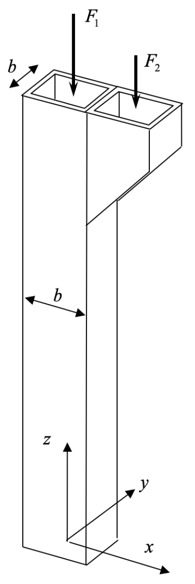

### 1. Ideal Buckling

We consider only the force $F_1$. The column can therefore been considered perfectly straight. 

- Make a schematic drawing of this column, assuming that the maximum deflection is $\delta$ in $z=L$. 

- Calculate the maximum force that can be applied to this column. Develop the equations and specify the bending plane of the columns. 

### 2. Eccentric axial load

We consider that both forces are applied to the columns. 

- Show that the system is equivalent to a force $F_{eq}$ applied at a distance $d$ from the column neutral axis. Calculate $d$.

- Establish the relation between the applied load and the column maximum displacement. 

- On a same graph, schematically plot the load-displacement curve of both cases. 

- We consider the load ratio $F_1/F_2 =3$. What maximum load can be applied to the column for a maximum displacement of $1\mathrm{cm}$ ?

- Where is the maximum stress in the column ? Give the literal expression of this stress and calculate the maximum value considering the forces defined in the former question.

**NA. **$E=70\,\mathrm{GPa}$ , $I=4.92\times10^{-10}\,\mathrm{m^4}$ , $L=2\,\mathrm{m}$

## I. Ideal Buckling

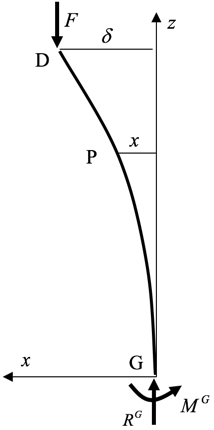

Let's call $F_1$ as $F$. We consider $F>0$, so that $\vec F=-F\vec z$, therefore $R^G=F$

$\vec{M^G}+\vec {GD}\times\vec F=0$ $\iff \vec {M^G}=-F\delta \vec y$   or  $M^G=-F\delta$

The bending moment in $\mathrm P$ is :


$$Mf=M^G+PG\times R^G \iff Mf_y=-F(\delta-x)$$
   

**Bresse equation** :

$\frac{d^2x}{dz^2}=-\frac{Mf_y}{EI_y}=\frac{F\delta-Fx}{EI}$       stating that $k^2=\frac{F}{EI}$

therefore : $\frac{d^2x}{dz^2}+k^2x=k^2\delta$

The general solution is :

clear all
syms k x(z) E I L d
assume(k ,'real')
eq1=diff(x,z,2)==-k^2*x+k^2*d

$$eq1(z) = \frac{\partial^{2}}{\partial z^{2}}x\left(z\right)=d\,k^{2}-k^{2}\,x\left(z\right)$$

x(z)=dsolve(eq1)

$$x(z) = d+C_{1}\,\cos\left(k\,z\right)-C_{2}\,\sin\left(k\,z\right)$$

syms C1 C2
x(z)=d+C1*cos(k*z)+C2*sin(k*z);
solve(x(0)==0,C1)

$$ans = -d$$

solve(diff(x(0),z)==0,C2)

$$ans = 0$$

x(z)=subs(x(z),C1,-d);
x(z)=subs(x(z),C2,0)

$$x(z) = d-d\,\cos\left(k\,z\right)$$

Boundary conditions in G : $x(0)=0$ and $x'(0)=0$


$$x(0)=0\iff C_1=-\delta$$



$$x'(0)=0\iff C_2=0$$


**The solution is therefore** : $x(z)=\delta (1-\cos kz)$

At the point D the solution is $x(L)=\delta$ $\iff \delta (1-\cos kL)=\delta \iff \delta\cos kL=0$

(i) $\delta=0$ meaning the undeflected column

(ii) $\cos kL=0\iff kL= \frac{\pi}{2},\,\frac{3\pi}{2},\,\frac{5\pi}{2},\, \dots$ ($\iff kL=(2n-1)\pi/2$ with $n=1,2,3,...$)

The critical value is the smallest one :


$$kL=\frac{\pi}{2}\iff \frac{F_c}{EI}=\frac{\pi^2}{4L^2}\iff F_c=\frac{\pi^2EI}{4L^2}$$


E=70e9; I=4.92e-10; L=2;
Fc=pi^2*E*I/4/L^2; fprintf(['Fc = %1.1f N'],Fc)

Fc = 21.2 N

## **II. eccentric loading**

**II.1 Calculation of the equivalent force** :

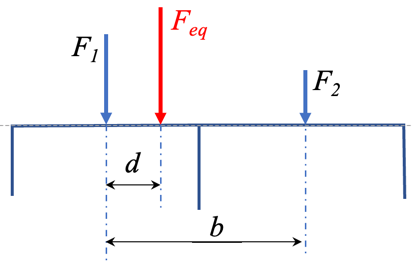

clear all
syms F1 F2 d b
solve(d*F1+(d-b)*F2==0,d)

$$ans = \frac{F_{2}\,b}{F_{1}+F_{2}}$$

$F_{eq}=F_1+F_2$ with $d=\frac {F_2b}{F_1+F_2}$

**II.2 Calculation of the displacement**

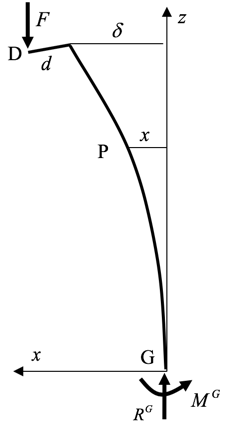

The calculation is similar to the former one, replacing $\delta$ by $\delta+d$, so that the differential equation is : $\frac{d^2x}{dz^2}+k^2x=k^2(\delta+d)$

the solution is therefore : $x(z)=C_1\cdot\cos kz+C_2\cdot\sin kz +\delta+d$

The boundary conditions are :


$$x(0)=0\iff C_1=-(\delta+d)$$



$$x'(0)=0\iff C_2=0$$


The displacement is therefore :


$$x(z)=(\delta+d)(1-\cos kz)$$


in $z=L$ the displacement is $x(L)=\delta$, replacing leads to :


$$\delta=(\delta+d)(1-\cos kL)$$
 
$$\iff d=(\delta+d)\cos kL$$
 
$$\iff \delta=\frac{d}{\cos kL}(1-\cos kL)$$


Replacing $k$ by its value, $k=\sqrt\frac{F_{eq}}{EI}$


$$\delta=\frac{d}{\cos \sqrt\frac{F_{eq}}{EI}L}(1-\cos \sqrt\frac{F_{eq}}{EI}L)$$


clear all
syms k x(z) E I L delta d F_eq
assume(k ,'real')
assume(L,'real')
eq1=diff(x,z,2)==-k^2*x+k^2*(delta+d)

$$eq1(z) = \frac{\partial^{2}}{\partial z^{2}}x\left(z\right)=k^{2}\,\left(d+\delta \right)-k^{2}\,x\left(z\right)$$

x(z)=dsolve(eq1)

$$x(z) = d+\delta +C_{1}\,\cos\left(k\,z\right)-C_{2}\,\sin\left(k\,z\right)$$

syms C1 C2
x(z)=d+delta+C1*cos(k*z)+C2*sin(k*z);
solve(x(0)==0,C1)

$$ans = -d-\delta$$

solve(diff(x(0),z)==0,C2)

$$ans = 0$$

x(z)=subs(x(z),C1,-d-delta);
x(z)=subs(x(z),C2,0)

$$x(z) = d+\delta -\cos\left(k\,z\right)\,\left(d+\delta \right)$$

delta=solve(x(L)==delta,delta)

$$delta = \frac{d-d\,\cos\left(L\,k\right)}{\cos\left(L\,k\right)}$$

delta=subs(delta,k,sqrt(F_eq/(E*I)))

$$delta = \frac{d-d\,\cos\left(L\,\sqrt{\frac{F_{\mathrm{eq}}}{\text{E}\,\text{I}}}\right)}{\cos\left(L\,\sqrt{\frac{F_{\mathrm{eq}}}{\text{E}\,\text{I}}}\right)}$$

**II.3 plot of the displacement curve**

Values of $F_1$ and $F_2$: $F_1/F_2=3$ and $F_1+F_2=F_c=21.24$

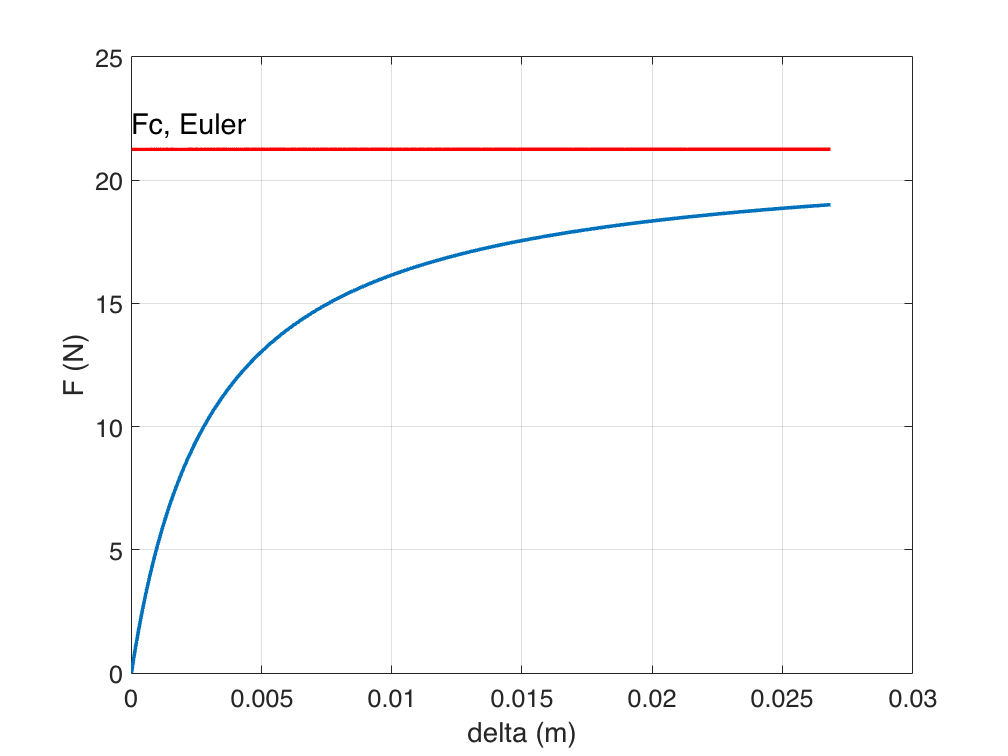

F2=21.24/4; F1=3*F2;
h=1e-2; e=1e-3; L=2; E=70e9; I=4.92e-10;
d=h*F2/(F1+F2);
Fc=pi^2*E*I/4/L^2;
F=0:0.1:19;
k=sqrt(F/(E*I));
delta=d./cos(k*L).*(1-cos(k*L));
plot(delta,F,'LineWidth',2)
hold on
F_eul=Fc+0*delta;
plot(delta,F_eul,'-r','LineWidth',2)
grid on
%axis([0,0.05,0,25]);
caractere=14;
xlabel('delta (m)','FontSize',caractere);
ylabel('F (N)','FontSize',caractere);
a = get(gca,'XTickLabel');
set(gca,'XTickLabel',a,'fontsize',caractere)
text(0,Fc*(1+0.05),'Fc, Euler','FontSize',16);
hold off

**II.4 maximum load**

del0=0.01;
del=@(F) d./cos(sqrt(F/(E*I))*L).*(1-cos(sqrt(F/(E*I))*L))-del0;
F_01=fzero(del,18);
fprintf('F_{d=0.01} = %1.2f N',F_01)

F_{d=0.01} = 16.15 N

ans = 1.4525e-06

%Second moment of area :

b=1e-2; h=1e-2; e=1e-3; 
I=(b*h^3-(b-2*e)*(h-2*e)^3)/12

I = 4.9200e-10

fprintf('I = %1.2e m^4',I)

I = 4.92e-10 m^4